# Actividad 1 (Mapeo de coordenadas)

Daniel Castillo López A01737357

**Implementar **el código requerido para generar un **mapeo** del siguiente sistema global al sistema local de referencia del robot móvil y viceversa.

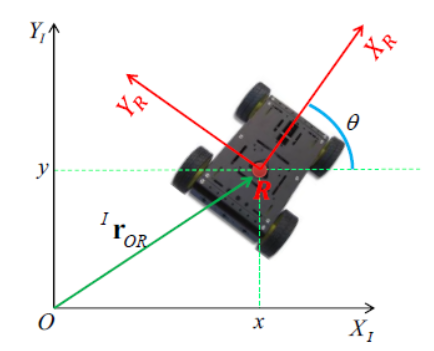

**Obtener** el mapeo de las siguientes coordenadas inerciales, hacia un marco de referencia local y comprobar si se obtienen las coordenadas iniciales con el mapeo inverso

Este documento explica el proceso de conversión de las coordenadas del robot en un plano 2D, utilizando estrategias matemáticas para realizar transformaciones entre marcos de referencia inercial y local. Se emplean variables simbólicas para modelar el posicionamiento y la orientación del robot en el espacio.

%Traducir la visón del robot sobre el cambio de posición, sabiendo las coordenadas
%del robot podemos emplear estrategias para aplicarlas en un plano 2D
%Cambiar los grados a radianes
clear all
close all
clc

## a) **(-5, 9, -2°)**

tic
%Declaración de variables simbólicas
syms xa(t) ya(t) tha(t) t %Ahora representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xi_inerciala= [xa; ya; tha];
    disp('Coordenadas generalizadas');pretty(xi_inerciala);

Coordenadas generalizadas
/  xa(t) \
|        |
|  ya(t) |
|        |
\ tha(t) /



    %Definimos un vector de velocidades
    xip_inerciala=diff(xi_inerciala,t);
    disp('Velocidades generalizadas');pretty(xip_inerciala);

Velocidades generalizadas
/   d       \
|  -- xa(t) |
|  dt       |
|           |
|   d       |
|  -- ya(t) |
|  dt       |
|           |
|  d        |
| -- tha(t) |
\ dt        /



### **Transformación de Coordenadas**

Se define el vector de posición y la matriz de rotación para transformar coordenadas entre marcos de referencia:

%Definimos mi vector de posición y matriz de rotación 
Pa(:,:,1)= [xa;ya;tha]; %Viene siendo "xi_inercial"
%Matriz de rotación al rededor del eje z

Ra(:,:,1)= [cos(tha) -sin(tha) 0;
           sin(tha) -cos(tha) 0;
           0          0     1];
xi_locala= Ra(:,:,1)*Pa(:,:,1)

$$xi\_locala = \left(\begin{array}{c} \cos\left(\mathrm{tha}\left(t\right)\right)\,\mathrm{xa}\left(t\right)-\sin\left(\mathrm{tha}\left(t\right)\right)\,\mathrm{ya}\left(t\right)\\ \sin\left(\mathrm{tha}\left(t\right)\right)\,\mathrm{xa}\left(t\right)-\cos\left(\mathrm{tha}\left(t\right)\right)\,\mathrm{ya}\left(t\right)\\ \mathrm{tha}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales para un tiempo 1
x1a=-5;       %Posición inicial eje x
y1a= 9;       %Posición inicial eje y
th1a = -2 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación para un tiempo 1
Pos_1a=[x1a; y1a; 0];
Rot_1a= [cos(th1a) -sin(th1a) 0;
        sin(th1a)  cos(th1a) 0;
        0         0      1];
 
%Realizo mi transformación del marco de referencia inercial al local.... 
xi_local_1a=Rot_1a*Pos_1a

xi_local_1a =    -4.6829
    9.1690
         0


### **Cálculo de la Magnitud del Vector Transformado**

%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1a(1)^2 + xi_local_1a(2)^2)

magnitud = 10.2956

### **Verificación de la Transformación**

Para comprobar que la transformación es correcta, se invierte la matriz de rotación y se multiplica por el vector transformado:

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xi_inercial_1a= inv_Rot_1a*xi_local_1a

xi_inercial_1a =    -5.0000
    9.0000
         0


toc

Elapsed time is 3.008752 seconds.


Este proceso permite transformar coordenadas entre marcos de referencia inercial y local, lo cual es fundamental para la navegación de robots en entornos 2D. La aplicación de matrices de rotación y el uso de variables simbólicas en MATLAB facilitan la manipulación y análisis del movimiento del robot.

## b) **(-3, 8, 63°)**

tic
%DeclaRbción de variables simbólicas
syms xb(t) yb(t) thb(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xi_inercialb= [xb; yb; thb];
    disp('Coordenadas generalizadas');pretty(xi_inercialb);

Coordenadas generalizadas
/  xb(t) \
|        |
|  yb(t) |
|        |
\ thb(t) /



    %Definimos un vector de velocidades
    xip_inercialb=diff(xi_inercialb,t);
    disp('Velocidades generalizadas');pretty(xip_inercialb);

Velocidades generalizadas
/   d       \
|  -- xb(t) |
|  dt       |
|           |
|   d       |
|  -- yb(t) |
|  dt       |
|           |
|  d        |
| -- thb(t) |
\ dt        /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xb;yb;thb]; %Viene siendo "xi_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(thb) -sin(thb) 0;
           sin(thb) -cos(thb) 0;
           0          0     1];
xi_localb= Rb(:,:,1)*Pb(:,:,1)

$$xi\_localb = \left(\begin{array}{c} \cos\left(\mathrm{thb}\left(t\right)\right)\,\mathrm{xb}\left(t\right)-\sin\left(\mathrm{thb}\left(t\right)\right)\,\mathrm{yb}\left(t\right)\\ \sin\left(\mathrm{thb}\left(t\right)\right)\,\mathrm{xb}\left(t\right)-\cos\left(\mathrm{thb}\left(t\right)\right)\,\mathrm{yb}\left(t\right)\\ \mathrm{thb}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1b=-3;       %Posición inicial eje x
y1b= 8;       %Posición inicial eje y
th1b = 63 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1b; y1b; 0];
Rot_1a= [cos(th1b) -sin(th1b) 0;
        sin(th1b)  cos(th1b) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xi_local_1a=Rot_1a*Pos_1a

xi_local_1a =    -8.4900
    0.9589
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1a(1)^2 + xi_local_1a(2)^2)

magnitud = 8.5440

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xi_inercial_1a= inv_Rot_1a*xi_local_1a

xi_inercial_1a =     -3
     8
     0


toc

Elapsed time is 1.342561 seconds.


## c) **(5, -2, 90°)**


tic
%DeclaRbción de variables simbólicas
syms xc(t) yc(t) thc(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xi_inercialb= [xc; yc; thc];
    disp('Coordenadas generalizadas');pretty(xi_inercialb);

Coordenadas generalizadas
/  xc(t) \
|        |
|  yc(t) |
|        |
\ thc(t) /



    %Definimos un vector de velocidades
    xip_inercialb=diff(xi_inercialb,t);
    disp('Velocidades generalizadas');pretty(xip_inercialb);

Velocidades generalizadas
/   d       \
|  -- xc(t) |
|  dt       |
|           |
|   d       |
|  -- yc(t) |
|  dt       |
|           |
|  d        |
| -- thc(t) |
\ dt        /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xc;yc;thc]; %Viene siendo "xi_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(thc) -sin(thc) 0;
           sin(thc) -cos(thc) 0;
           0          0     1];
xi_localb= Rb(:,:,1)*Pb(:,:,1)

$$xi\_localb = \left(\begin{array}{c} \cos\left(\mathrm{thc}\left(t\right)\right)\,\mathrm{xc}\left(t\right)-\sin\left(\mathrm{thc}\left(t\right)\right)\,\mathrm{yc}\left(t\right)\\ \sin\left(\mathrm{thc}\left(t\right)\right)\,\mathrm{xc}\left(t\right)-\cos\left(\mathrm{thc}\left(t\right)\right)\,\mathrm{yc}\left(t\right)\\ \mathrm{thc}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1c=-5;       %Posición inicial eje x
y1c= -2;       %Posición inicial eje y
th1c = 90 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1c; y1c; 0];
Rot_1a= [cos(th1c) -sin(th1c) 0;
        sin(th1c)  cos(th1c) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xi_local_1a=Rot_1a*Pos_1a

xi_local_1a =     2.0000
   -5.0000
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1a(1)^2 + xi_local_1a(2)^2)

magnitud = 5.3852

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xi_inercial_1a= inv_Rot_1a*xi_local_1a

xi_inercial_1a =     -5
    -2
     0


toc

Elapsed time is 1.124986 seconds.


## d) **(0, 0, 180°)**

tic
%DeclaRbción de variables simbólicas
syms xd(t) yd(t) thd(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xi_inercialb= [xd; yd; thd];
    disp('Coordenadas generalizadas');pretty(xi_inercialb);

Coordenadas generalizadas
/  xd(t) \
|        |
|  yd(t) |
|        |
\ thd(t) /



    %Definimos un vector de velocidades
    xip_inercialb=diff(xi_inercialb,t);
    disp('Velocidades generalizadas');pretty(xip_inercialb);

Velocidades generalizadas
/   d       \
|  -- xd(t) |
|  dt       |
|           |
|   d       |
|  -- yd(t) |
|  dt       |
|           |
|  d        |
| -- thd(t) |
\ dt        /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xd;yd;thd]; %Viene siendo "xi_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(thd) -sin(thd) 0;
           sin(thd) -cos(thd) 0;
           0          0     1];
xi_localb= Rb(:,:,1)*Pb(:,:,1)

$$xi\_localb = \left(\begin{array}{c} \cos\left(\mathrm{thd}\left(t\right)\right)\,\mathrm{xd}\left(t\right)-\sin\left(\mathrm{thd}\left(t\right)\right)\,\mathrm{yd}\left(t\right)\\ \sin\left(\mathrm{thd}\left(t\right)\right)\,\mathrm{xd}\left(t\right)-\cos\left(\mathrm{thd}\left(t\right)\right)\,\mathrm{yd}\left(t\right)\\ \mathrm{thd}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1d=0;       %Posición inicial eje x
y1d= 0;       %Posición inicial eje y
th1d = 180 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1d; y1d; 0];
Rot_1a= [cos(th1d) -sin(th1d) 0;
        sin(th1d)  cos(th1d) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xi_local_1a=Rot_1a*Pos_1a

xi_local_1a =      0
     0
     0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1a(1)^2 + xi_local_1a(2)^2)

magnitud = 0

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xi_inercial_1a= inv_Rot_1a*xi_local_1a

xi_inercial_1a =      0
     0
     0


toc

Elapsed time is 0.926390 seconds.


## e) **(-6, 3, -55°)**

tic
%DeclaRbción de variables simbólicas
syms xe(t) ye(t) the(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xi_inercialb= [xe; ye; the];
    disp('Coordenadas generalizadas');pretty(xi_inercialb);

Coordenadas generalizadas
/  xe(t) \
|        |
|  ye(t) |
|        |
\ the(t) /



    %Definimos un vector de velocidades
    xip_inercialb=diff(xi_inercialb,t);
    disp('Velocidades generalizadas');pretty(xip_inercialb);

Velocidades generalizadas
/   d       \
|  -- xe(t) |
|  dt       |
|           |
|   d       |
|  -- ye(t) |
|  dt       |
|           |
|  d        |
| -- the(t) |
\ dt        /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xe;ye;the]; %Viene siendo "xi_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(the) -sin(the) 0;
           sin(the) -cos(the) 0;
           0          0     1];
xi_localb= Rb(:,:,1)*Pb(:,:,1)

$$xi\_localb = \left(\begin{array}{c} \cos\left(\mathrm{the}\left(t\right)\right)\,\mathrm{xe}\left(t\right)-\sin\left(\mathrm{the}\left(t\right)\right)\,\mathrm{ye}\left(t\right)\\ \sin\left(\mathrm{the}\left(t\right)\right)\,\mathrm{xe}\left(t\right)-\cos\left(\mathrm{the}\left(t\right)\right)\,\mathrm{ye}\left(t\right)\\ \mathrm{the}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1e=-6;       %Posición inicial eje x
y1e= 3;       %Posición inicial eje y
th1e = -55 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1e; y1e; 0];
Rot_1a= [cos(th1e) -sin(th1e) 0;
        sin(th1e)  cos(th1e) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xi_local_1a=Rot_1a*Pos_1a

xi_local_1a =    -0.9840
    6.6356
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1a(1)^2 + xi_local_1a(2)^2)

magnitud = 6.7082

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xi_inercial_1a= inv_Rot_1a*xi_local_1a

xi_inercial_1a =    -6.0000
    3.0000
         0


toc

Elapsed time is 1.017893 seconds.


## f) **(10, -2, 45°) **

tic
%DeclaRbción de variables simbólicas
syms xf(t) yf(t) thf(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xi_inercialb= [xf; yf; thf];
    disp('Coordenadas generalizadas');pretty(xi_inercialb);

Coordenadas generalizadas
/  xf(t) \
|        |
|  yf(t) |
|        |
\ thf(t) /



    %Definimos un vector de velocidades
    xip_inercialb=diff(xi_inercialb,t);
    disp('Velocidades generalizadas');pretty(xip_inercialb);

Velocidades generalizadas
/   d       \
|  -- xf(t) |
|  dt       |
|           |
|   d       |
|  -- yf(t) |
|  dt       |
|           |
|  d        |
| -- thf(t) |
\ dt        /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xf;yf;thf]; %Viene siendo "xi_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(thf) -sin(thf) 0;
           sin(thf) -cos(thf) 0;
           0          0     1];
xi_localb= Rb(:,:,1)*Pb(:,:,1)

$$xi\_localb = \left(\begin{array}{c} \cos\left(\mathrm{thf}\left(t\right)\right)\,\mathrm{xf}\left(t\right)-\sin\left(\mathrm{thf}\left(t\right)\right)\,\mathrm{yf}\left(t\right)\\ \sin\left(\mathrm{thf}\left(t\right)\right)\,\mathrm{xf}\left(t\right)-\cos\left(\mathrm{thf}\left(t\right)\right)\,\mathrm{yf}\left(t\right)\\ \mathrm{thf}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1f=10;       %Posición inicial eje x
y1f=-2;       %Posición inicial eje y
th1f = 45 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1f; y1f; 0];
Rot_1a= [cos(th1f) -sin(th1f) 0;
        sin(th1f)  cos(th1f) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xi_local_1a=Rot_1a*Pos_1a

xi_local_1a =     8.4853
    5.6569
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1a(1)^2 + xi_local_1a(2)^2)

magnitud = 10.1980

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xi_inercial_1a= inv_Rot_1a*xi_local_1a

xi_inercial_1a =     10
    -2
     0


toc

Elapsed time is 0.812016 seconds.


## g) **(9, 1, 88°)**

tic
%DeclaRbción de variables simbólicas
syms xg(t) yg(t) thg(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xi_inercialb= [xg; yg; thg];
    disp('Coordenadas generalizadas');pretty(xi_inercialb);

Coordenadas generalizadas
/  xg(t) \
|        |
|  yg(t) |
|        |
\ thg(t) /



    %Definimos un vector de velocidades
    xip_inercialb=diff(xi_inercialb,t);
    disp('Velocidades generalizadas');pretty(xip_inercialb);

Velocidades generalizadas
/   d       \
|  -- xg(t) |
|  dt       |
|           |
|   d       |
|  -- yg(t) |
|  dt       |
|           |
|  d        |
| -- thg(t) |
\ dt        /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xg;yg;thg]; %Viene siendo "xi_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(thg) -sin(thg) 0;
           sin(thg) -cos(thg) 0;
           0          0     1];
xi_localb= Rb(:,:,1)*Pb(:,:,1)

$$xi\_localb = \left(\begin{array}{c} \cos\left(\mathrm{thg}\left(t\right)\right)\,\mathrm{xg}\left(t\right)-\sin\left(\mathrm{thg}\left(t\right)\right)\,\mathrm{yg}\left(t\right)\\ \sin\left(\mathrm{thg}\left(t\right)\right)\,\mathrm{xg}\left(t\right)-\cos\left(\mathrm{thg}\left(t\right)\right)\,\mathrm{yg}\left(t\right)\\ \mathrm{thg}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1g=9;       %Posición inicial eje x
y1g= 1;       %Posición inicial eje y
th1g = 88 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1g; y1g; 0];
Rot_1a= [cos(th1g) -sin(th1g) 0;
        sin(th1g)  cos(th1g) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xi_local_1a=Rot_1a*Pos_1a

xi_local_1a =    -0.6853
    9.0294
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1a(1)^2 + xi_local_1a(2)^2)

magnitud = 9.0554

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xi_inercial_1a= inv_Rot_1a*xi_local_1a

xi_inercial_1a =      9
     1
     0


toc

Elapsed time is 0.848595 seconds.


## h) **(5, 2, 33°)**

tic
%DeclaRbción de variables simbólicas
syms xh(t) yh(t) thh(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xi_inercialb= [xh; yh; thh];
    disp('Coordenadas generalizadas');pretty(xi_inercialb);

Coordenadas generalizadas
/  xh(t) \
|        |
|  yh(t) |
|        |
\ thh(t) /



    %Definimos un vector de velocidades
    xip_inercialb=diff(xi_inercialb,t);
    disp('Velocidades generalizadas');pretty(xip_inercialb);

Velocidades generalizadas
/   d       \
|  -- xh(t) |
|  dt       |
|           |
|   d       |
|  -- yh(t) |
|  dt       |
|           |
|  d        |
| -- thh(t) |
\ dt        /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xh;yh;thh]; %Viene siendo "xi_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(thh) -sin(thh) 0;
           sin(thh) -cos(thh) 0;
           0          0     1];
xi_localb= Rb(:,:,1)*Pb(:,:,1)

$$xi\_localb = \left(\begin{array}{c} \cos\left(\mathrm{thh}\left(t\right)\right)\,\mathrm{xh}\left(t\right)-\sin\left(\mathrm{thh}\left(t\right)\right)\,\mathrm{yh}\left(t\right)\\ \sin\left(\mathrm{thh}\left(t\right)\right)\,\mathrm{xh}\left(t\right)-\cos\left(\mathrm{thh}\left(t\right)\right)\,\mathrm{yh}\left(t\right)\\ \mathrm{thh}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1h=5;       %Posición inicial eje x
y1h=2;       %Posición inicial eje y
th1h = 33 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1h; y1h; 0];
Rot_1a= [cos(th1h) -sin(th1h) 0;
        sin(th1h)  cos(th1h) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xi_local_1a=Rot_1a*Pos_1a

xi_local_1a =     3.1041
    4.4005
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1a(1)^2 + xi_local_1a(2)^2)

magnitud = 5.3852

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xi_inercial_1a= inv_Rot_1a*xi_local_1a

xi_inercial_1a =      5
     2
     0


toc

Elapsed time is 0.913153 seconds.


## i) **(-1, -1, 21°)**

tic
%DeclaRbción de variables simbólicas
syms xi(t) yi(t) thi(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xi_inercialb= [xi; yi; thi];
    disp('Coordenadas generalizadas');pretty(xi_inercialb);

Coordenadas generalizadas
/  ξ(t)  \
|        |
|  yi(t) |
|        |
\ thi(t) /



    %Definimos un vector de velocidades
    xip_inercialb=diff(xi_inercialb,t);
    disp('Velocidades generalizadas');pretty(xip_inercialb);

Velocidades generalizadas
/   d       \
|  -- ξ(t)  |
|  dt       |
|           |
|   d       |
|  -- yi(t) |
|  dt       |
|           |
|  d        |
| -- thi(t) |
\ dt        /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xi;yi;thi]; %Viene siendo "xi_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(thi) -sin(thi) 0;
           sin(thi) -cos(thi) 0;
           0          0     1];
xi_localb= Rb(:,:,1)*Pb(:,:,1)

$$xi\_localb = \left(\begin{array}{c} \cos\left(\mathrm{thi}\left(t\right)\right)\,\xi \left(t\right)-\sin\left(\mathrm{thi}\left(t\right)\right)\,\mathrm{yi}\left(t\right)\\ \sin\left(\mathrm{thi}\left(t\right)\right)\,\xi \left(t\right)-\cos\left(\mathrm{thi}\left(t\right)\right)\,\mathrm{yi}\left(t\right)\\ \mathrm{thi}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1i=-1;       %Posición inicial eje x
y1i=-1;       %Posición inicial eje y
th1i = 21 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1i; y1i; 0];
Rot_1a= [cos(th1i) -sin(th1i) 0;
        sin(th1i)  cos(th1i) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xi_local_1a=Rot_1a*Pos_1a

xi_local_1a =    -0.5752
   -1.2919
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xi_local_1a(1)^2 + xi_local_1a(2)^2)

magnitud = 1.4142

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xi_inercial_1a= inv_Rot_1a*xi_local_1a

xi_inercial_1a =    -1.0000
   -1.0000
         0


toc

Elapsed time is 0.910632 seconds.


## j) **(6, 4, -40°)**

tic
%DeclaRbción de variables simbólicas
syms xj(t) yj(t) thj(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xj_inercialb= [xj; yj; thj];
    disp('Coordenadas generalizadas');pretty(xj_inercialb);

Coordenadas generalizadas
/  xj(t) \
|        |
|  yj(t) |
|        |
\ thj(t) /



    %Definimos un vector de velocidades
    xjp_inercialb=diff(xj_inercialb,t);
    disp('Velocidades generalizadas');pretty(xjp_inercialb);

Velocidades generalizadas
/   d       \
|  -- xj(t) |
|  dt       |
|           |
|   d       |
|  -- yj(t) |
|  dt       |
|           |
|  d        |
| -- thj(t) |
\ dt        /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xj;yj;thj]; %Viene siendo "xj_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(thj) -sin(thj) 0;
           sin(thj) -cos(thj) 0;
           0          0     1];
xj_localb= Rb(:,:,1)*Pb(:,:,1)

$$xj\_localb = \left(\begin{array}{c} \cos\left(\mathrm{thj}\left(t\right)\right)\,\mathrm{xj}\left(t\right)-\sin\left(\mathrm{thj}\left(t\right)\right)\,\mathrm{yj}\left(t\right)\\ \sin\left(\mathrm{thj}\left(t\right)\right)\,\mathrm{xj}\left(t\right)-\cos\left(\mathrm{thj}\left(t\right)\right)\,\mathrm{yj}\left(t\right)\\ \mathrm{thj}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1j= 6;       %Posición inicial eje x
y1j= 4;       %Posición inicial eje y
th1j = -40 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1j; y1j; 0];
Rot_1a= [cos(th1j) -sin(th1j) 0;
        sin(th1j)  cos(th1j) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xj_local_1a=Rot_1a*Pos_1a

xj_local_1a =     7.1674
   -0.7925
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xj_local_1a(1)^2 + xj_local_1a(2)^2)

magnitud = 7.2111

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xj_inercial_1a= inv_Rot_1a*xj_local_1a

xj_inercial_1a =     6.0000
    4.0000
         0


toc

Elapsed time is 0.803951 seconds.


## k) **(5, 7, 72°)**

tic
%DeclaRbción de variables simbólicas
syms xk(t) yk(t) thk(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xk_inercialb= [xk; yk; thk];
    disp('Coordenadas generalizadas');pretty(xk_inercialb);

Coordenadas generalizadas
/  xk(t) \
|        |
|  yk(t) |
|        |
\ thk(t) /



    %Definimos un vector de velocidades
    xkp_inercialb=diff(xk_inercialb,t);
    disp('Velocidades generalizadas');pretty(xkp_inercialb);

Velocidades generalizadas
/   d       \
|  -- xk(t) |
|  dt       |
|           |
|   d       |
|  -- yk(t) |
|  dt       |
|           |
|  d        |
| -- thk(t) |
\ dt        /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xk;yk;thk]; %Viene siendo "xk_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(thk) -sin(thk) 0;
           sin(thk) -cos(thk) 0;
           0          0     1];
xk_localb= Rb(:,:,1)*Pb(:,:,1)

$$xk\_localb = \left(\begin{array}{c} \cos\left(\mathrm{thk}\left(t\right)\right)\,\mathrm{xk}\left(t\right)-\sin\left(\mathrm{thk}\left(t\right)\right)\,\mathrm{yk}\left(t\right)\\ \sin\left(\mathrm{thk}\left(t\right)\right)\,\mathrm{xk}\left(t\right)-\cos\left(\mathrm{thk}\left(t\right)\right)\,\mathrm{yk}\left(t\right)\\ \mathrm{thk}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1k=-5;       %Posición inicial eje x
y1k= 7;       %Posición inicial eje y
th1k = 72 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1k; y1k; 0];
Rot_1a= [cos(th1k) -sin(th1k) 0;
        sin(th1k)  cos(th1k) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xk_local_1a=Rot_1a*Pos_1a

xk_local_1a =    -8.2025
   -2.5922
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xk_local_1a(1)^2 + xk_local_1a(2)^2)

magnitud = 8.6023

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xk_inercial_1a= inv_Rot_1a*xk_local_1a

xk_inercial_1a =     -5
     7
     0


toc

Elapsed time is 0.791026 seconds.


## l) **(7, 7,  30°)**

tic
%DeclaRbción de variables simbólicas
syms xl(t) yl(t) thl(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xl_inercialb= [xl; yl; thl];
    disp('Coordenadas generalizadas');pretty(xl_inercialb);

Coordenadas generalizadas
/  xl(t) \
|        |
|  yl(t) |
|        |
\ thl(t) /



    %Definimos un vector de velocidades
    xlp_inercialb=diff(xl_inercialb,t);
    disp('Velocidades generalizadas');pretty(xlp_inercialb);

Velocidades generalizadas
/   d       \
|  -- xl(t) |
|  dt       |
|           |
|   d       |
|  -- yl(t) |
|  dt       |
|           |
|  d        |
| -- thl(t) |
\ dt        /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xl;yl;thl]; %Viene siendo "xl_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(thl) -sin(thl) 0;
           sin(thl) -cos(thl) 0;
           0          0     1];
xl_localb= Rb(:,:,1)*Pb(:,:,1)

$$xl\_localb = \left(\begin{array}{c} \cos\left(\mathrm{thl}\left(t\right)\right)\,\mathrm{xl}\left(t\right)-\sin\left(\mathrm{thl}\left(t\right)\right)\,\mathrm{yl}\left(t\right)\\ \sin\left(\mathrm{thl}\left(t\right)\right)\,\mathrm{xl}\left(t\right)-\cos\left(\mathrm{thl}\left(t\right)\right)\,\mathrm{yl}\left(t\right)\\ \mathrm{thl}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1l=7;       %Posición inicial eje x
y1l=7;       %Posición inicial eje y
th1l = 30 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1l; y1l; 0];
Rot_1a= [cos(th1l) -sin(th1l) 0;
        sin(th1l)  cos(th1l) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xl_local_1a=Rot_1a*Pos_1a

xl_local_1a =     2.5622
    9.5622
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xl_local_1a(1)^2 + xl_local_1a(2)^2)

magnitud = 9.8995

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xl_inercial_1a= inv_Rot_1a*xl_local_1a

xl_inercial_1a =     7.0000
    7.0000
         0


toc

Elapsed time is 0.760326 seconds.


## m) **(11, -4, 360°)**

tic
%DeclaRbción de variables simbólicas
syms xm(t) ym(t) thm(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xm_inercialb= [xm; ym; thm];
    disp('Coordenadas generalizadas');pretty(xm_inercialb);

Coordenadas generalizadas
/  xm(t) \
|        |
|  ym(t) |
|        |
\ thm(t) /



    %Definimos un vector de velocidades
    xmp_inercialb=diff(xm_inercialb,t);
    disp('Velocidades generalizadas');pretty(xmp_inercialb);

Velocidades generalizadas
/   d       \
|  -- xm(t) |
|  dt       |
|           |
|   d       |
|  -- ym(t) |
|  dt       |
|           |
|  d        |
| -- thm(t) |
\ dt        /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xm;ym;thm]; %Viene siendo "xm_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(thm) -sin(thm) 0;
           sin(thm) -cos(thm) 0;
           0          0     1];
xm_localb= Rb(:,:,1)*Pb(:,:,1)

$$xm\_localb = \left(\begin{array}{c} \cos\left(\mathrm{thm}\left(t\right)\right)\,\mathrm{xm}\left(t\right)-\sin\left(\mathrm{thm}\left(t\right)\right)\,\mathrm{ym}\left(t\right)\\ \sin\left(\mathrm{thm}\left(t\right)\right)\,\mathrm{xm}\left(t\right)-\cos\left(\mathrm{thm}\left(t\right)\right)\,\mathrm{ym}\left(t\right)\\ \mathrm{thm}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1m= 11;       %Posición inicial eje x
y1m= -4;       %Posición inicial eje y
th1m =360 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1m; y1m; 0];
Rot_1a= [cos(th1m) -sin(th1m) 0;
        sin(th1m)  cos(th1m) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xm_local_1a=Rot_1a*Pos_1a

xm_local_1a =    11.0000
   -4.0000
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xm_local_1a(1)^2 + xm_local_1a(2)^2)

magnitud = 11.7047

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xm_inercial_1a= inv_Rot_1a*xm_local_1a

xm_inercial_1a =     11
    -4
     0


toc

Elapsed time is 0.796027 seconds.


## n) **(20, 5, 270°)**

tic
%DeclaRbción de variables simbólicas
syms xn(t) yn(t) thn(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xn_inercialb= [xn;yn; thn];
    disp('Coordenadas generalizadas');pretty(xn_inercialb);

Coordenadas generalizadas
/  xn(t) \
|        |
|  yn(t) |
|        |
\ thn(t) /



    %Definimos un vector de velocidades
    xnp_inercialb=diff(xn_inercialb,t);
    disp('Velocidades generalizadas');pretty(xnp_inercialb);

Velocidades generalizadas
/   d       \
|  -- xn(t) |
|  dt       |
|           |
|   d       |
|  -- yn(t) |
|  dt       |
|           |
|  d        |
| -- thn(t) |
\ dt        /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xn;ym;thn]; %Viene siendo "xn_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(thn) -sin(thn) 0;
           sin(thn) -cos(thn) 0;
           0          0     1];
xn_localb= Rb(:,:,1)*Pb(:,:,1)

$$xn\_localb = \left(\begin{array}{c} \cos\left(\mathrm{thn}\left(t\right)\right)\,\mathrm{xn}\left(t\right)-\sin\left(\mathrm{thn}\left(t\right)\right)\,\mathrm{ym}\left(t\right)\\ \sin\left(\mathrm{thn}\left(t\right)\right)\,\mathrm{xn}\left(t\right)-\cos\left(\mathrm{thn}\left(t\right)\right)\,\mathrm{ym}\left(t\right)\\ \mathrm{thn}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1n= 20;       %Posición inicial eje x
y1n= 5;       %Posición inicial eje y
th1n = 270 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1n; y1n; 0];
Rot_1a= [cos(th1n) -sin(th1n) 0;
        sin(th1n)  cos(th1n) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xn_local_1a=Rot_1a*Pos_1a

xn_local_1a =     5.0000
  -20.0000
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xn_local_1a(1)^2 + xn_local_1a(2)^2)

magnitud = 20.6155

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xn_inercial_1a= inv_Rot_1a*xn_local_1a

xn_inercial_1a =     20
     5
     0


toc

Elapsed time is 0.737993 seconds.


## ñ) **(10, 9, 345°)**

tic
%DeclaRbción de variables simbólicas
syms xnn(t) ynn(t) thnn(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xnn_inercialb= [xnn;ynn; thnn];
    disp('Coordenadas generalizadas');pretty(xnn_inercialb);

Coordenadas generalizadas
/  xnn(t) \
|         |
|  ynn(t) |
|         |
\ thnn(t) /



    %Definimos un vector de velocidades
    xnnp_inercialb=diff(xnn_inercialb,t);
    disp('Velocidades generalizadas');pretty(xnnp_inercialb);

Velocidades generalizadas
/   d        \
|  -- xnn(t) |
|  dt        |
|            |
|   d        |
|  -- ynn(t) |
|  dt        |
|            |
|  d         |
| -- thnn(t) |
\ dt         /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xnn;ym;thnn]; %Viene siendo "xnn_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(thnn) -sin(thnn) 0;
           sin(thnn) -cos(thnn) 0;
           0          0     1];
xnn_localb= Rb(:,:,1)*Pb(:,:,1)

$$xnn\_localb = \left(\begin{array}{c} \cos\left(\mathrm{thnn}\left(t\right)\right)\,\mathrm{xnn}\left(t\right)-\sin\left(\mathrm{thnn}\left(t\right)\right)\,\mathrm{ym}\left(t\right)\\ \sin\left(\mathrm{thnn}\left(t\right)\right)\,\mathrm{xnn}\left(t\right)-\cos\left(\mathrm{thnn}\left(t\right)\right)\,\mathrm{ym}\left(t\right)\\ \mathrm{thnn}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1nn=10;       %Posición inicial eje x
y1nn= 9;       %Posición inicial eje y
th1nn = 345 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1nn; y1nn; 0];
Rot_1a= [cos(th1nn) -sin(th1nn) 0;
        sin(th1nn)  cos(th1nn) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xnn_local_1a=Rot_1a*Pos_1a

xnn_local_1a =    11.9886
    6.1051
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xnn_local_1a(1)^2 + xnn_local_1a(2)^2)

magnitud = 13.4536

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xnn_inercial_1a= inv_Rot_1a*xnn_local_1a

xnn_inercial_1a =    10.0000
    9.0000
         0


toc

Elapsed time is 0.791668 seconds.


## o) **(-9, -8, 8°)**

tic
%DeclaRbción de variables simbólicas
syms xo(t) yo(t) tho(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xo_inercialb= [xo;yo; tho];
    disp('Coordenadas generalizadas');pretty(xo_inercialb);

Coordenadas generalizadas
/  xo(t) \
|        |
|  yo(t) |
|        |
\ tho(t) /



    %Definimos un vector de velocidades
    xop_inercialb=diff(xo_inercialb,t);
    disp('Velocidades generalizadas');pretty(xop_inercialb);

Velocidades generalizadas
/   d       \
|  -- xo(t) |
|  dt       |
|           |
|   d       |
|  -- yo(t) |
|  dt       |
|           |
|  d        |
| -- tho(t) |
\ dt        /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xo;ym;tho]; %Viene siendo "xo_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(tho) -sin(tho) 0;
           sin(tho) -cos(tho) 0;
           0          0     1];
xo_localb= Rb(:,:,1)*Pb(:,:,1)

$$xo\_localb = \left(\begin{array}{c} \cos\left(\mathrm{tho}\left(t\right)\right)\,\mathrm{xo}\left(t\right)-\sin\left(\mathrm{tho}\left(t\right)\right)\,\mathrm{ym}\left(t\right)\\ \sin\left(\mathrm{tho}\left(t\right)\right)\,\mathrm{xo}\left(t\right)-\cos\left(\mathrm{tho}\left(t\right)\right)\,\mathrm{ym}\left(t\right)\\ \mathrm{tho}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1o=-9;       %Posición inicial eje x
y1o=-8;       %Posición inicial eje y
th1o = 8 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1o; y1o; 0];
Rot_1a= [cos(th1o) -sin(th1o) 0;
        sin(th1o)  cos(th1o) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xo_local_1a=Rot_1a*Pos_1a

xo_local_1a =    -7.7990
   -9.1747
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xo_local_1a(1)^2 + xo_local_1a(2)^2)

magnitud = 12.0416

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xo_inercial_1a= inv_Rot_1a*xo_local_1a

xo_inercial_1a =    -9.0000
   -8.0000
         0


toc

Elapsed time is 0.713576 seconds.


## p) **(1, 1, 60°)**

tic
%DeclaRbción de variables simbólicas
syms xp(t) yp(t) thp(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xp_inercialb= [xp;yp; thp];
    disp('Coordenadas generalizadas');pretty(xp_inercialb);

Coordenadas generalizadas
/  xp(t) \
|        |
|  yp(t) |
|        |
\ thp(t) /



    %Definimos un vector de velocidades
    xpp_inercialb=diff(xp_inercialb,t);
    disp('Velocidades generalizadas');pretty(xpp_inercialb);

Velocidades generalizadas
/   d       \
|  -- xp(t) |
|  dt       |
|           |
|   d       |
|  -- yp(t) |
|  dt       |
|           |
|  d        |
| -- thp(t) |
\ dt        /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xp;ym;thp]; %Viene siendo "xp_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(thp) -sin(thp) 0;
           sin(thp) -cos(thp) 0;
           0          0     1];
xp_localb= Rb(:,:,1)*Pb(:,:,1)

$$xp\_localb = \left(\begin{array}{c} \cos\left(\mathrm{thp}\left(t\right)\right)\,\mathrm{xp}\left(t\right)-\sin\left(\mathrm{thp}\left(t\right)\right)\,\mathrm{ym}\left(t\right)\\ \sin\left(\mathrm{thp}\left(t\right)\right)\,\mathrm{xp}\left(t\right)-\cos\left(\mathrm{thp}\left(t\right)\right)\,\mathrm{ym}\left(t\right)\\ \mathrm{thp}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1p=1;       %Posición inicial eje x
y1p=1;       %Posición inicial eje y
th1p = 60 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1p; y1p; 0];
Rot_1a= [cos(th1p) -sin(th1p) 0;
        sin(th1p)  cos(th1p) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xp_local_1a=Rot_1a*Pos_1a

xp_local_1a =    -0.3660
    1.3660
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xp_local_1a(1)^2 + xp_local_1a(2)^2)

magnitud = 1.4142

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xp_inercial_1a= inv_Rot_1a*xp_local_1a

xp_inercial_1a =     1.0000
    1.0000
         0


toc

Elapsed time is 0.759049 seconds.


## q) **(3, 1, -30°)**

tic
%DeclaRbción de variables simbólicas
syms xq(t) yq(t) thq(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xq_inercialb= [xq;yq; thq];
    disp('Coordenadas generalizadas');pretty(xq_inercialb);

Coordenadas generalizadas
/  xq(t) \
|        |
|  yq(t) |
|        |
\ thq(t) /



    %Definimos un vector de velocidades
    xqp_inercialb=diff(xq_inercialb,t);
    disp('Velocidades generalizadas');pretty(xqp_inercialb);

Velocidades generalizadas
/   d       \
|  -- xq(t) |
|  dt       |
|           |
|   d       |
|  -- yq(t) |
|  dt       |
|           |
|  d        |
| -- thq(t) |
\ dt        /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xq;ym;thq]; %Viene siendo "xq_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(thq) -sin(thq) 0;
           sin(thq) -cos(thq) 0;
           0          0     1];
xq_localb= Rb(:,:,1)*Pb(:,:,1)

$$xq\_localb = \left(\begin{array}{c} \cos\left(\mathrm{thq}\left(t\right)\right)\,\mathrm{xq}\left(t\right)-\sin\left(\mathrm{thq}\left(t\right)\right)\,\mathrm{ym}\left(t\right)\\ \sin\left(\mathrm{thq}\left(t\right)\right)\,\mathrm{xq}\left(t\right)-\cos\left(\mathrm{thq}\left(t\right)\right)\,\mathrm{ym}\left(t\right)\\ \mathrm{thq}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1q=3;       %Posición inicial eje x
y1q=1;       %Posición inicial eje y
th1q = -30 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1q; y1q; 0];
Rot_1a= [cos(th1q) -sin(th1q) 0;
        sin(th1q)  cos(th1q) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xq_local_1a=Rot_1a*Pos_1a

xq_local_1a =     3.0981
   -0.6340
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xq_local_1a(1)^2 + xq_local_1a(2)^2)

magnitud = 3.1623

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xq_inercial_1a= inv_Rot_1a*xq_local_1a

xq_inercial_1a =     3.0000
    1.0000
         0


toc

Elapsed time is 0.824439 seconds.


## r) **(15, 2, 199°)**

tic
%DeclaRbción de variables simbólicas
syms xr(t) yr(t) thr(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xr_inercialb= [xr;yr; thr];
    disp('Coordenadas generalizadas');pretty(xr_inercialb);

Coordenadas generalizadas
/  xr(t) \
|        |
|  yr(t) |
|        |
\ thr(t) /



    %Definimos un vector de velocidades
    xrp_inercialb=diff(xr_inercialb,t);
    disp('Velocidades generalizadas');pretty(xrp_inercialb);

Velocidades generalizadas
/   d       \
|  -- xr(t) |
|  dt       |
|           |
|   d       |
|  -- yr(t) |
|  dt       |
|           |
|  d        |
| -- thr(t) |
\ dt        /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xr;ym;thr]; %Viene siendo "xr_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(thr) -sin(thr) 0;
           sin(thr) -cos(thr) 0;
           0          0     1];
xr_localb= Rb(:,:,1)*Pb(:,:,1)

$$xr\_localb = \left(\begin{array}{c} \cos\left(\mathrm{thr}\left(t\right)\right)\,\mathrm{xr}\left(t\right)-\sin\left(\mathrm{thr}\left(t\right)\right)\,\mathrm{ym}\left(t\right)\\ \sin\left(\mathrm{thr}\left(t\right)\right)\,\mathrm{xr}\left(t\right)-\cos\left(\mathrm{thr}\left(t\right)\right)\,\mathrm{ym}\left(t\right)\\ \mathrm{thr}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1r= 15;       %Posición inicial eje x
y1r= 2;       %Posición inicial eje y
th1r = 199 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1r; y1r; 0];
Rot_1a= [cos(th1r) -sin(th1r) 0;
        sin(th1r)  cos(th1r) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xr_local_1a=Rot_1a*Pos_1a

xr_local_1a =   -13.5316
   -6.7746
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xr_local_1a(1)^2 + xr_local_1a(2)^2)

magnitud = 15.1327

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xr_inercial_1a= inv_Rot_1a*xr_local_1a

xr_inercial_1a =    15.0000
    2.0000
         0


toc

Elapsed time is 0.796100 seconds.


## s) **(-10, 0, 300°)**

tic
%DeclaRbción de variables simbólicas
syms xs(t) ys(t) ths(t) t %AhoRb representan nuestro posicionamiento del robot

%Creamos el vector de posición
    xs_inercialb= [xs;ys; ths];
    disp('Coordenadas generalizadas');pretty(xs_inercialb);

Coordenadas generalizadas
/  xs(t) \
|        |
|  ys(t) |
|        |
\ ths(t) /



    %Definimos un vector de velocidades
    xsp_inercialb=diff(xs_inercialb,t);
    disp('Velocidades generalizadas');pretty(xsp_inercialb);

Velocidades generalizadas
/   d       \
|  -- xs(t) |
|  dt       |
|           |
|   d       |
|  -- ys(t) |
|  dt       |
|           |
|  d        |
| -- ths(t) |
\ dt        /




%Definimos mi vector de posición y matriz de rotación 
Pb(:,:,1)= [xs;ym;ths]; %Viene siendo "xs_inercial"
%Matriz de rotación al rededor del eje z

Rb(:,:,1)= [cos(ths) -sin(ths) 0;
           sin(ths) -cos(ths) 0;
           0          0     1];
xs_localb= Rb(:,:,1)*Pb(:,:,1)

$$xs\_localb = \left(\begin{array}{c} \cos\left(\mathrm{ths}\left(t\right)\right)\,\mathrm{xs}\left(t\right)-\sin\left(\mathrm{ths}\left(t\right)\right)\,\mathrm{ym}\left(t\right)\\ \sin\left(\mathrm{ths}\left(t\right)\right)\,\mathrm{xs}\left(t\right)-\cos\left(\mathrm{ths}\left(t\right)\right)\,\mathrm{ym}\left(t\right)\\ \mathrm{ths}\left(t\right) \end{array}\right)$$

%Inercial=Global
%Coordenadas globales, definicmos coordenadas unerciales PbRb un tiempo 1
x1s= -10;       %Posición inicial eje x
y1s=  0;       %Posición inicial eje y
th1s = 300 * pi/180; %Orientación inicial del robot

%Defino mi vector de posición y matriz de rotación PbRb un tiempo 1
Pos_1a=[x1s; y1s; 0];
Rot_1a= [cos(th1s) -sin(th1s) 0;
        sin(th1s)  cos(th1s) 0;
        0         0      1];
 
%Realizo mi tRbnsformación del marco de referencia inercial al local.... 
xs_local_1a=Rot_1a*Pos_1a

xs_local_1a =    -5.0000
    8.6603
         0



%Obtengo la magnitud del vector resultante 
magnitud= sqrt(xs_local_1a(1)^2 + xs_local_1a(2)^2)

magnitud = 10

%Compruebo que me devuelva el vector inercial 
inv_Rot_1a= inv(Rot_1a);
xs_inercial_1a= inv_Rot_1a*xs_local_1a

xs_inercial_1a =   -10.0000
    0.0000
         0


toc

Elapsed time is 0.728737 seconds.
